# CNT iEEG Pre-processing Pipeline

This notebook provides a recommended usage pipeline for the iEEG pre-processing toolkit.

## Set Paths

The work path should be the path to the 'matlab' toolkit folder.

%set path
 
work_path = "/Users/meow/Documents/GitHub/CNT_research_tools/matlab";
cd(work_path);
paths;
% Add path to this codebase
addpath(genpath(work_path))
runtests('test/dependTest'); % ensure dependencies exist

Running dependTest
.
Done dependTest
__________



## Pipeline Implementation

Showcase of usage and recommended order of functions.

### Initialize Session

Initialize iEEGPreprocess session.

Suggested syntax:

 
session = iEEGPreprocess();

### Login Configuration

Set up iEEG.org login info for obtaining data.

Suggesteed syntax:

For first-time users:

 
session.login_config();

Login:

 
session.login();

Login as : qaq233tvt


### Available Methods

**Arguments:**

- datasets: cell of data instances

- meta: metadata as a table with columns | filename | start | stop | dura | fs |

- num_data: number of data instances available

- users: cell of available iEEG login usernames

- user: struct, user information of the active account

- user_data_dir: str, default path to save user data

**Methods:**

- download_data: download data from ieeg.org

- list_data: list meta info

- remove_data: remove certain data instance

- load_data: load data from saved pickle files

- login: login with default or specified username

- login_config: input username and password info to create config files

- save: save session as .mat file

### Get Data via Input

Specify the filename, start/stop time, electrodes, etc.

- **File name:** the name of target file at ieeg.org

- **Start time: **the start time of target clip in seconds 

- **Stop time: **the stop time of target clip in seconds 

- **Include electrodes (optional): **manually define a set of electrodes to be included in analysis

- **Exclude electrodes (optional): **manually define a set of electrodes to be excluded in analysis

file_name = 'HUP172_phaseII';
start = 402580;
stop = 402600;
select_elecs = strsplit('LE10, LE11, LH01, LH02, LH03, LH04',', ','CollapseDelimiters',false);
ignore_elecs = strsplit('',', ','CollapseDelimiters',false);
assert(~isempty(file_name),'CNTtools:invalidInput','No test case to run.');
if isempty(select_elecs{1})
    select_elecs = {};
end
if isempty(ignore_elecs{1})
    ignore_elecs = {};
end

### Download data

Download data from ieeg.org.

Suggested syntax:

 
data = session.download_data(file_name, start, stop, select_elecs, ignore_elecs);

### Available Methods for Data Instance

**Arguments:**

- filename/start/stop: inputs

- select_elects: selected channels for downloading

- ignore_elecs: channels excluded from downloading

- dura: duration of data segment

- data: active data array after pre-processing

- fs: sampling frequency

- ch_names: active channel names after pre-processing

- ref_chnames: channel names after re-referencing

- index: dataset index in current session

- conn: diction storing connectivity data

- history: operations done on data object

- raw: raw data array

- raw_chs: raw channel names

- username: ieeg username

- user_data_dir: str, default path to save user data

- nonieeg: boolean mask for non-intracranial channels

- bad: boolean mask for channels containing artifacts

- reject_details: reasons for identify bad channels

**Methods:**

Channels:

- clean_labels: standardize channel names

- find_nonieeg: identify non-iEEG channels

- find_bad_chs: identify bad channels containing artifacts

- reject_nonieeg: identify and remove non-iEEG channels

- reject_artifact: identify and remove artifact channels

Filtering:

- bandpass_filter: apply bandpass filter

- notch_filter: apply notch filter

Re-referencing:

- reref: re-referencing with chosen method

- car: common average re-referencing

- bipolar: bipolar re-referencing

- laplacian: laplacian re-referencing

Connectivity:

- connectivity: calculate various connectivity

- coherence: calculate coherence

- cross_corr: calculate cross correlation

- pearson: calculate pearson correlation

- plv: calculate phase-locking value

- relative_entropy: calculate relative entropy

- squared_pearson: calculate squared pearson correlation

Calculate features:

- bandpower: calculate bandpower

- line_length: calculate linelength

Plotting:

- plot: plot data

- conn_heatmap: plot connectivity matrix using heatmap

Others:

- load_locs: load electrode location information from .csv file

- pre_whiten: pre-whitening of iEEG data

- reverse: reverse operation by one step

- save: save session as pickle file

### Identifiy Non-iEEG channels

Find and return a boolean mask for Non-iEEG channels, 0 = iEEG, 1 = Non-iEEG

Suggested syntax:

 
data.find_nonieeg();

IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****


nonieeg_table = cell2table(data.ch_names(data.nonieeg),"VariableNames",["Non-iEEG Channels"])

### Identifiy Bad Channels

Find and return a boolean mask for bad channels (1 = bad channels), and details for reasons to reject.

Suggested syntax:

 
%% Identify bad channels
data.find_bad_chs();


nonieeg_table = 2×1 table
    Non-iEEG Channels
    _________________

        {'EKG1'}     
        {'EKG2'}     


% for test
bad_table = cell2table(data.ch_names(data.bad),"VariableNames",["Bad Channels"])
disp('Specific reasons for being rejected:')
for i = fieldnames(data.reject_details)'
    disp(strcat([i{1},': ',strjoin(data.ch_names(data.reject_details.(i{1})))]));
end

### Clean Data

Reject Non-iEEG channels.

Suggested syntax:

Reject bad hannels containing artifacts

Suggested syntax:

 
data.reject_nonieeg()
data.reject_artifact()

### Filtering

Filter iEEG signal with bandpass and notch filter. 

Default setting: lower threshold 1Hz, higher threshold 120Hz, notch frequency 60Hz.

Suggested syntax:

 
low_freq = 1;

bad_table = 3×1 table
    Bad Channels
    ____________

      {'RE8' }  
      {'RE9' }  
      {'RE10'}  


high_freq = 120;

Specific reasons for being rejected:


notch_freq = 60;
data.bandpass_filter(low_freq,high_freq)
data.notch_filter(notch_freq)

noisy:
nans:
zeros:
var:
higher_std: RE8 RE9 RE10
high_voltage:


### Re-referencing

Re-reference data to a different montage

Available options:

- Common Average Re-referencing (CAR)

- Bipolar Re-referencing (BR)

- Laplacian Re-referencing (LAR): Note, requires location of electrodes and radius threshold

Suggested syntax:

 
which_reference = 'laplacian';
loc_file = 'elec_locs.csv';
radius = 20;
data.reref(which_reference,loc_file,radius);

### Prewhitening (optional)

Suggested syntax:

 
data.pre_whiten();

### Feature Calculation

Calculate features such as bandpower and linelength

Suggested syntax:

bands = [1,15;25,50]; 
 
data.bandpower(bands)
ll = data.line_length();

### Plot Data

Generate plot of time-series data

Suggested syntax:

 
fig = data.plot();
% set(gcf,'position',[0,0,500,500])
title('Sample Data')

### Connectivity Analysis

Connectivity analysis using various methods.

Available options:

- Pearson Correlation

- Squared Pearson

- Cross Correlation

- Coherence

- Phase-Locking Value (PLV)

- Relative Entropy

Suggested syntax:

 
judge = [true,true,true,true,true,true];
conn_method = {'pearson', 'squared_pearson', 'cross_corr', 'coh', 'plv', 'rela_entropy'};
data.connectivity(conn_method(judge));

### Connectivity Heatmap

Heatmap plot of calculated connectivity matrix.

Suggested syntax:

 
conn_method = "pearson";
freq_band = "broad";
fig2 = data.conn_heatmap(conn_method,freq_band);

### Save data

Save data in .mat format

Suggested syntax:

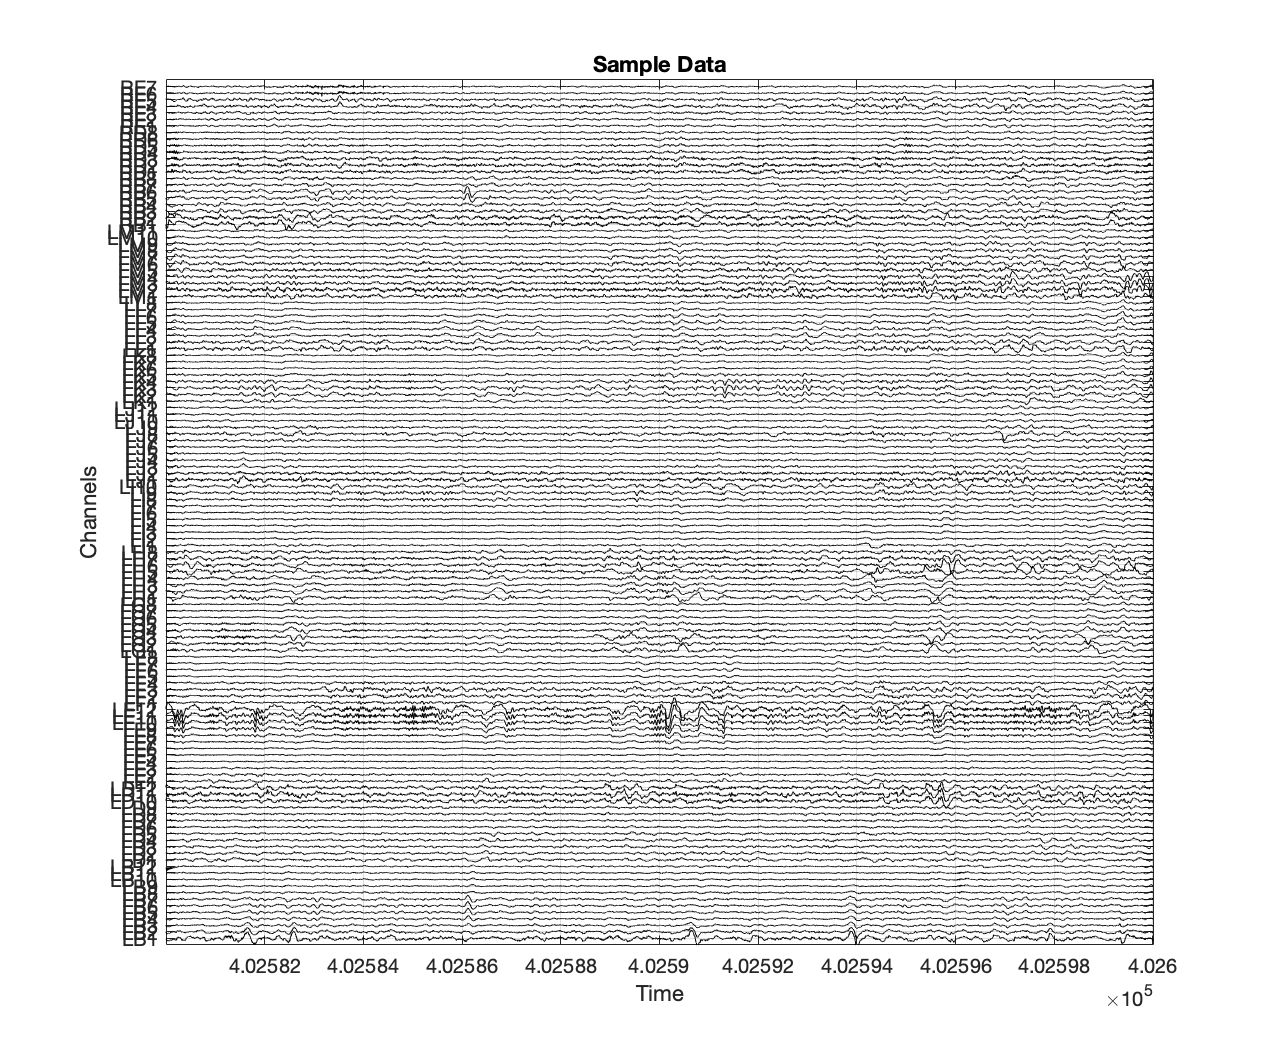

 
filename = "session_test";
session.save(filename)
% data.save()

### Load data

Load saved .mat format data

Suggested syntax:

 
session.load_data('')
session.list_data()

### Remove data

Remove certain data instances from session.

Suggested syntax:

 
session.remove_data(2);
session.list_data();

## Batch Processing

### Get Data via File

**File upload:** Input file should be of .csv/.tsv format, with columns labeled as:

- **filename**: *string*, the name of target file at ieeg.org

- **start: ***numeric*, the start time of target clip in seconds 

- **stop: ***numeric*, the stop time of target clip in seconds 

- **selecElecs: ***string*, electrodes to be included in analysis, separated by ', '

- **ignoreElecs: ***string*, electrodes to be excluded in analysis, separated by ', '

filePath = 'test/pipelineTest/pipeline_testInput.csv';
assert(~isempty(filePath),'CNTtools:invalidInput','No test case to run.');
assert(exist(filePath,'file')==2,'CNTtools:dependencyUnavailable','Specified file not exist.')

param = table2struct(readtable(filePath,'Format','auto'));

### Settings

Filtering Settings:

low_freq = 1;
high_freq = 120;
notch_freq = 60;

Re-ref Setting:

which_reference = 'laplacian';
loc_file = 'elec_locs.csv';

        filename        start      stop     dura    fs 
    ________________    ______    ______    ____    ___

    "HUP172_phaseII"    402580    402600     20     512
    "HUP172_phaseII"    402580    402600     20     512



radius = 20;

Pre-whitening Setting:

pre_white = false;

Feature Calculation Setting:

bp = true;

        filename        start      stop     dura    fs 
    ________________    ______    ______    ____    ___

    "HUP172_phaseII"    402580    402600     20     512



relative = true;
bands = [1,15;25,50];
linelength = true;

Connectivity Setting:

judge = [true,true,true,true,true,true];
conn_method = {'pearson', 'squared_pearson', 'cross_corr', 'coh', 'plv', 'rela_entropy'};
window = true;
window_size = 2;

If save output data files:

ifsave = true;

Save to default folder:

default_folder = true;

Or save to a specified folder:

save_path = '';
if ~isempty(save_path) && exist(save_path,'dir')~=2
    mkdir(save_path);
end
addpath(genpath(save_path));
 


 
session = iEEGPreprocess();
session.login();
for i = 1:length(param)
    file_name = param(i).filename;
    start = param(i).start;
    stop = param(i).stop;
%     if isnan(param(i).selecElecs)
        select_elecs = {};
%     else
%         select_elecs = strsplit(param(i).selecElecs,', ','CollapseDelimiters',false);
%     end
%     if isnan(param(i).ignoreElecs)
        ignore_elecs = {};
%     else
%         ignore_elecs = strsplit(param(i).ignoreElecs,', ','CollapseDelimiters',false);
%     end
    data = session.download_data(file_name, start, stop, select_elecs, ignore_elecs);
    data.clean_labels();
    data.reject_nonieeg();
    data.reject_artifact();
    data.filter(low_freq,high_freq,notch_freq);
    data.reref(which_reference,loc_file,radius);
    if pre_white
        data.pre_whiten();
    end

Login as : qaq233tvt


    if bp
        data.bandpower(bands,[],relative);
    end
    if linelength
        data.line_length()
    end
    data.connectivity(conn_method(judge),window,window_size);
    if ifsave
        data.save(save_path,default_folder)
    end
end

IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****
18:25:56,972 ERROR edu.upenn.cis.db.mefview.services.TimeSeriesInterface:770 - caught exception
edu.upenn.cis.db.mefview.services.IeegWsRemoteException: An error response with status 500 (Internal Server Error) was returned from the server
	at edu.upenn.cis.db.mefview.services.IeegWsErrorHandler.responseToException(IeegWsErrorHandler.java:88)
	at edu.upenn.cis.db.mefview.services.IeegWsErrorHandler.handleErrorClientResponse(IeegWsErrorHandler.java:45)
	at edu.upenn.cis.db.mefview.services.TimeSeriesInterface.getUnscaledTimeSeriesSetRaw(TimeSeriesInterface.java:619)


IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****
